% 아래와 같은 분포를 갖는 독립적인 n개의 random variables의 합으로 
% 새로운 r.v.을 생성하여 central limit theorem 확인 (새로운 r.v.의 개수= 10^7)
% Uniform Distribution (0 ≤ x ≤ 1)
% (a) n = 3      (b) n = 6      (c) n = 12      (d) n = 20
% 0부터 1사이에서 uniform distribution을 갖는 n개의 r.v.들의 합으로 새로운 r.v.을 생성한다.

## n = 3

sgtitle('after standard')
arr1 = zeros(1,10^7);
for cnt = 1:3
    for i = 1:10^7
        arr1(i) = arr1(i) + rand();
    end
end

m1 = mean(arr1); v1 = var(arr1);
% standard normal rv
std1 = (arr1-m1).*(1/sqrt(v1))

std1 =     2.0018   -0.4143   -0.1902   -0.5296    0.5550   -0.6373   -1.3804    0.5772    2.0154    0.1600    0.4377    0.3364    1.6517    1.1459    0.1596    0.5759   -1.3679   -0.9467    0.1911   -0.3479   -1.0273    1.2565    2.2182   -1.2360   -0.4968   -0.0823   -1.9065   -0.0756    1.3246    0.5898   -0.6447   -0.1546   -2.0499    1.3476   -1.1439    0.6149   -0.4708   -2.0303   -0.2845    1.2808    0.2882    0.4250   -0.0074    0.8181   -0.8402   -1.0707    0.6307    2.1512   -0.1752    0.8921


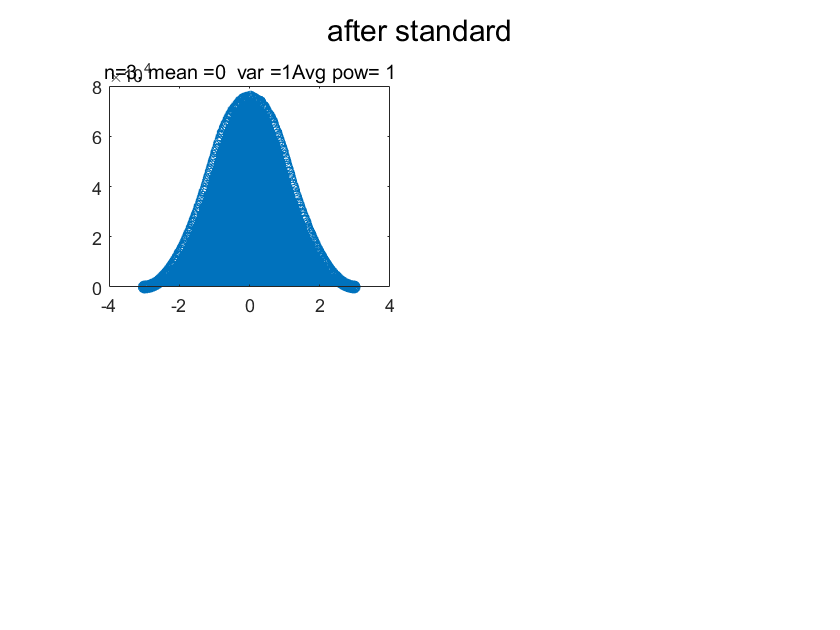

m1 = round(mean(std1),2); v1 = round(var(std1),2);
p1 = round(mean(std1.^2),2);
[N1,~] = histcounts(std1);
subplot(2,2,1)
stem(linspace(min(std1),max(std1),length(N1)),N1)
title(['n=3, mean =',num2str(m1),'  var =',num2str(v1),'Avg pow= ',num2str(p1)])

% histogram(arr1) <- matlab doesn't recommand it

## n = 6

arr2 = zeros(1,10^7);
for cnt = 1:6
    for i = 1:10^7
        arr2(i) = arr2(i) + rand();
    end
end

m2 = mean(arr2); v2 = var(arr2);
std2 = (arr2 - m2).*(1/sqrt(v2))

std2 =    -0.4294    0.2195    0.2577   -1.0878    1.7237    0.7142   -0.7433   -1.7466    0.3867    0.0581   -1.3979   -0.8819   -0.3115    0.2507   -1.0823   -1.1918   -0.3254   -0.6800    0.4918   -0.2678   -0.7400   -0.5557   -0.1673    0.7414   -1.7092    1.3473    0.0376    1.8042    0.0648    0.5339    0.0758   -0.5636    1.8745   -0.6476    0.1521    1.3916   -0.6078   -1.3596    1.9847   -0.3901   -0.7073   -0.1491   -0.7664    1.3930    0.7524    0.3872    0.1992    0.6442    0.7853    0.8961


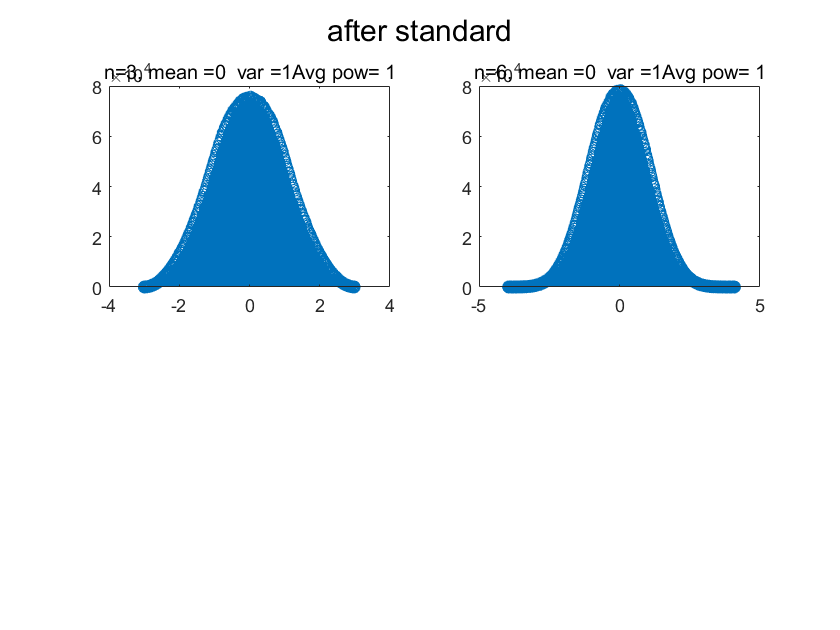

m2 = round(mean(std2),2); v2 = round(var(std2),2);
p2 = round(mean(std2.^2),2);
[N2,~] = histcounts(std2);
subplot(2,2,2)
stem(linspace(min(std2),max(std2),length(N2)),N2)
title(['n=6, mean =',num2str(m2),'  var =',num2str(v2),'Avg pow= ',num2str(p2)])

## n = 12

arr3 = zeros(1,10^7);
for cnt = 1:12
    for i = 1:10^7
        arr3(i) = arr3(i) + rand();
    end
end
m3 = mean(arr3); v3 = var(arr3);
std3 = (arr3 - m3).*(1/sqrt(v3))

std3 =    -0.4686    0.0352   -0.8234   -0.5735    0.3479    0.0459    1.1655    0.7951    1.2695   -1.4301    2.1407   -0.8187   -1.8596    0.0186    0.3567    0.2590    0.7695    2.2372   -0.7689   -0.3563    1.0680    0.1498   -0.4941    1.2696    0.6655    1.5345   -0.6548    1.7235    0.2132   -1.2172   -0.7212    0.3656   -0.2574   -1.0297    0.5401    1.1982   -0.5486   -1.0166   -0.1869    2.0179   -1.8921    1.3954    0.9451    0.5185   -0.1392   -0.2857   -0.2114    1.6725   -0.2289   -0.3239


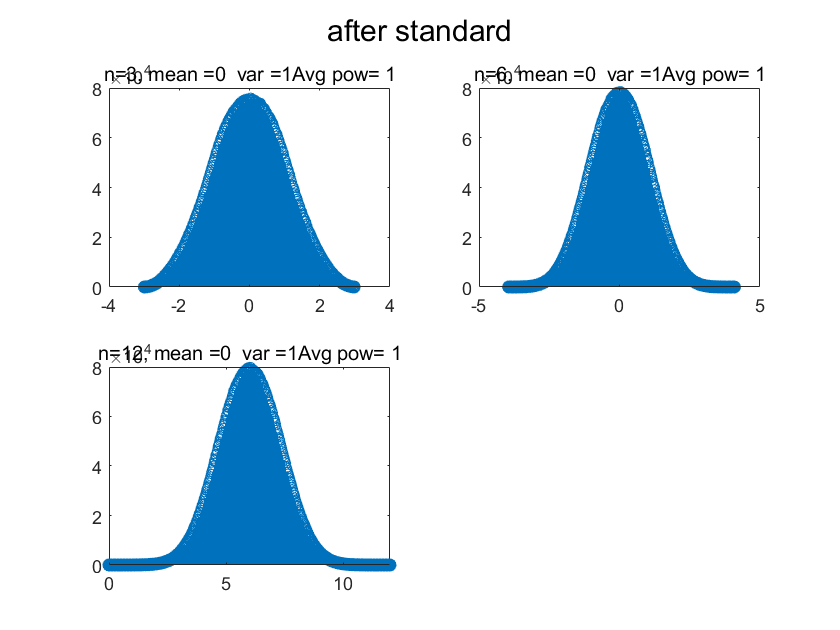

m3 = round(mean(std3),2); v3 = round(var(std3),2);
p3 = round(mean(std3.^2),2);
[N3,~] = histcounts(std3);
subplot(2,2,3)
stem(linspace(0,12,length(N3)),N3)
title(['n=12, mean =',num2str(m3),'  var =',num2str(v3),'Avg pow= ',num2str(p3)])
xlim([0,12])

## n = 20

arr4 = zeros(1,10^7);
for cnt = 1:20
    for i = 1:10^7
        arr4(i) = arr4(i) + rand();
    end
end
m4 = mean(arr4); v4 = var(arr4);
std4 = (arr4 - m4).*(1/sqrt(v4))

std4 =     1.2993    0.1415    0.6282    0.7125    0.0469    0.8738    0.8684    0.0884    1.2719   -1.9247    0.3169    0.2229   -0.2219    0.4690    1.1696    1.4216   -0.0239   -0.7264    0.3627    0.1843    0.1496    0.3185   -3.0849    1.0169    0.3585   -0.5353    2.0823    0.2947    1.5418   -0.9960   -0.4187    1.0631    0.6913    0.5774    0.9006    0.0913    1.5435   -0.8099   -0.4992   -1.0586   -0.3112    0.0732   -2.4736   -1.7336   -0.4691    0.0140   -0.0465    0.9936   -1.3171    0.2610


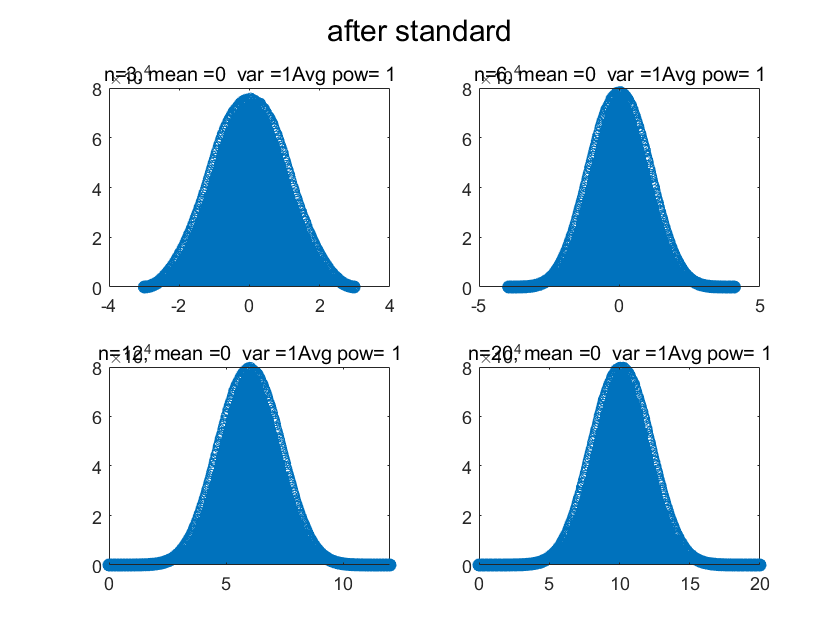

m4 = round(mean(std4),2); v4 = round(var(std4),2);
p4 = round(mean(std4.^2),2);
[N4,~] = histcounts(std4);
subplot(2,2,4)
stem(linspace(0,20,length(N4)),N4)
title(['n=20, mean =',num2str(m4),'  var =',num2str(v4),'Avg pow= ',num2str(p4)])